**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP6: HACHEUR SÉRIE RÉGULÉ EN TENSION  

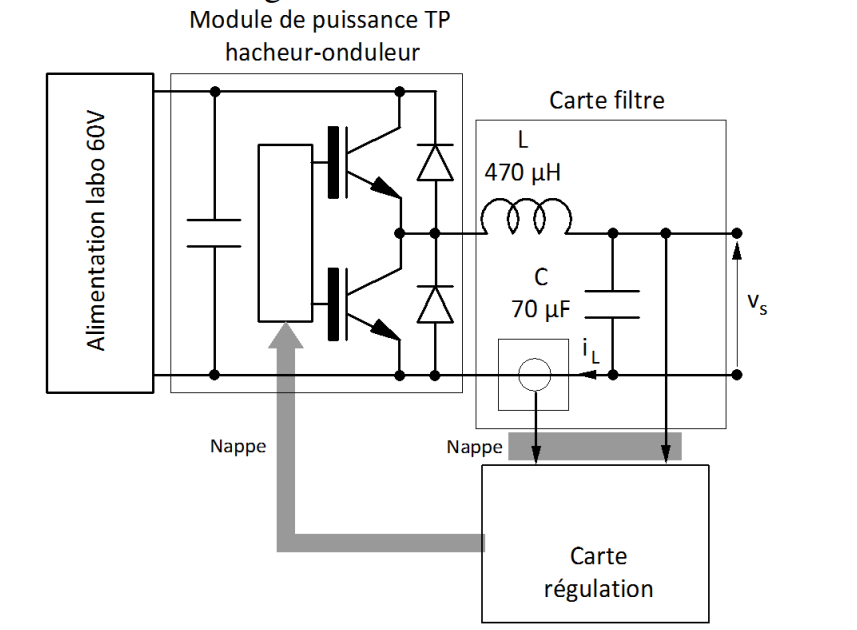

### 3. Étude en régime permanent

#### 3.1. Etude en boucle fermée : efficacité de l’action de la régulation vis-à-vis des

variations de la tension d'entrée VE 

Pour tout le TP on a 2 condensateur de 4,7nF

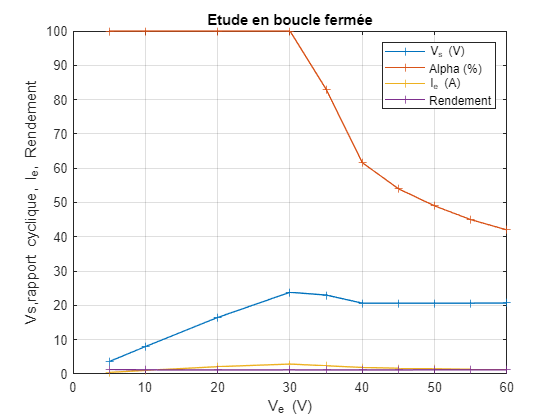

Ve=[60 55 50 45 40 35 30 20 10 5];%10 valeurs de Ve
Vs=[20.7 20.66 20.65 20.64 20.66 23.02 23.83 16.48 7.99 3.62];
alpha=[42 45 49 54 61.6 83 100 100 100 100];
iE=[1.28 1.38 1.52 1.69 1.91 2.40 2.90 2.14 1.04 0.47];
iS=[3.047 3.050 3.052 3.069 3.086 3.090 3.027 2.219 1.077 0.487];
rendement=(Ve.*iE)./(Vs.*iS); 
plot(Ve,Vs,'+-',Ve,alpha,'+-',Ve,iE,'+-',Ve,rendement,'+-');
title('Etude en boucle fermée')
xlabel('V_e (V)'); ylabel('Vs,rapport cyclique, I_e, Rendement')
legend('V_s (V)','Alpha (%)','I_e (A)','Rendement')
grid on

Dans cette première partie, nous faisons varier la tension d'entrée après avoir réglé une tension de consigne égale à 20V, c'est à dire que la tension de sortie du hacheur doit rester égal à 20V, qu'importe la tension d'entrée.

De 0 à 20V, le rapport cyclique est égal à 100% et la tension de sortie est environ égale à la tension d'entrée. Ce comportement s'explique par la tension en entrée du hacheur qui est trop faible pour que l'on puisse respecter la consigne (Vs=20V). On a donc la tension d'entrée égal à la tension de sortie (donc $\alpha =100%$).

De 20V à 60V, le rapport cyclique décroit : pour rappel, $V_S =\alpha V_e$. En sortie du hacheur, la tension est alors égale à 20V. De plus, le courant en entrée et en sortie sont quand à eux constant, preuve que la régulation se fait sur le rapport cyclique.

#### 3.2. Etude en boucle ouverte : effet de la tension d'entrée VE

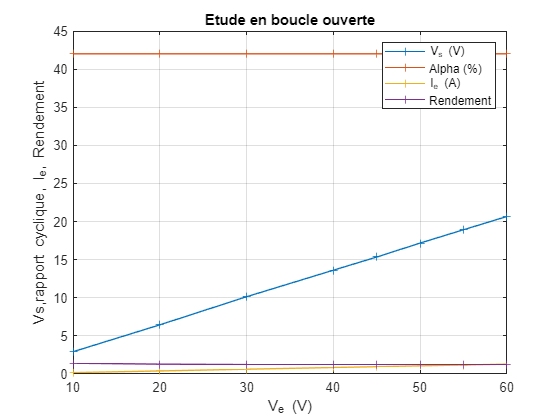

Ve2=[60 55 50 45 40 30 20 10];% 8 valeurs de Ve
Vs2=[20.67 18.93 17.18 15.35 13.62 10.14 6.45 2.92];
alpha2=[42 42 42 42 42 42 42 42];
iE2=[1.29 1.18 1.07 0.96 0.85 0.63 0.4 0.18];
iS2=[3.077 2.815 2.558 2.281 2.027 1.506 0.960 0.435];
rendement2=(Ve2.*iE2)./(Vs2.*iS2); %Trouver la valeur de iS
plot(Ve2,Vs2,'+-',Ve2,alpha2,'+-',Ve2,iE2,'+-',Ve2,rendement2,'+-');
title('Etude en boucle ouverte')
xlabel('V_e (V)'); ylabel('Vs,rapport cyclique, I_e, Rendement')
legend('V_s (V)','Alpha (%)','I_e (A)','Rendement')
grid on

En boucle ouverte, nous n'avons pas de contre réaction : le rapport cyclique ne va donc pas varier en fonction de Ve et va rester constant. Nous aurons donc une tension de sortie qui ne respectera pas la consigne, même pour Ve compris entre 20 et 60V.

#### 3.3. Etude en boucle ouverte : effet du courant appelé par la charge sur VS  

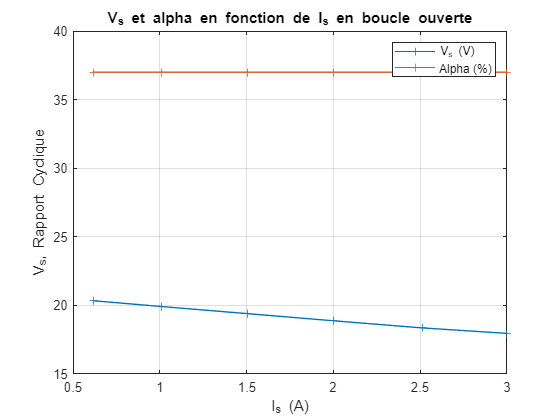

iS3=[0.617 1.007 1.504 1.999 2.511 3.0]; %7 valeurs de iS
Vs3=[20.34 19.92 19.40 18.88 18.36 17.96];
alpha3=[37 37 37 37 37 37];

plot(iS3,Vs3,'+-',iS3,alpha3,'+-'); % La courbe pour alpha doit etre constante
title('V_s et alpha en fonction de I_s en boucle ouverte')
xlabel('I_s (A)'); ylabel('V_s, Rapport Cyclique')
legend('V_s (V)','Alpha (%)')
grid on

Ce qui nous interesse sur ce graphique est la variation de Vs en fonction du courant de sortie puisque nous sommes dans un cas sans contre réaction (le rapport cyclique reste constant).

Nous pouvons observer que la tension de sortie est inversement proportionnelle au courant de sortie : plus Is augmente, plus Vs diminue. Cette évolution s'explique par la puissance (pour rappel, $P=U\times I$) : nous avons la même puissance en entrée et en sortie du hacheur, et puisque le rapport cyclique ne varie pas et le courant augmente, alors la tension de sortie va diminuer.

#### 3.4. Etude en boucle fermée : effet du courant appelé par la charge sur VS  

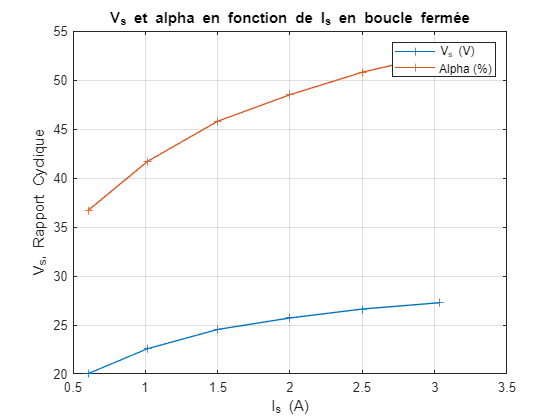

iS4=[0.605 1.015 1.501 2.00 2.50 3.03]; %7 valeurs de iS
Vs4=[20.04 22.58 24.55 25.72 26.63 27.27];
alpha4=[36.7 41.7 45.8 48.5 50.8 52.6];

plot(iS4,Vs4,'+-',iS4,alpha4,'+-'); % La courbe pour alpha doit varier
title('V_s et alpha en fonction de I_s en boucle fermée')
xlabel('I_s (A)'); ylabel('V_s, Rapport Cyclique')
legend('V_s (V)','Alpha (%)')
grid on

Comparé à la boucle ouverte, nous pouvons observer dans un premier temps que le rapport cyclique évolue en fonction du courant en sortie : plus le courant augmente, plus rapport cyclique augmente également.

Ensuite, la tension de sortie du hacheur augmente en fonction du courant 

### 4. Étude en régime dynamique (PARTIE A FAIRE SI ON EST RAPIDO !!!!!!!!!!)

#### 4.1. Objectif de l'étude dynamique

Débranchement

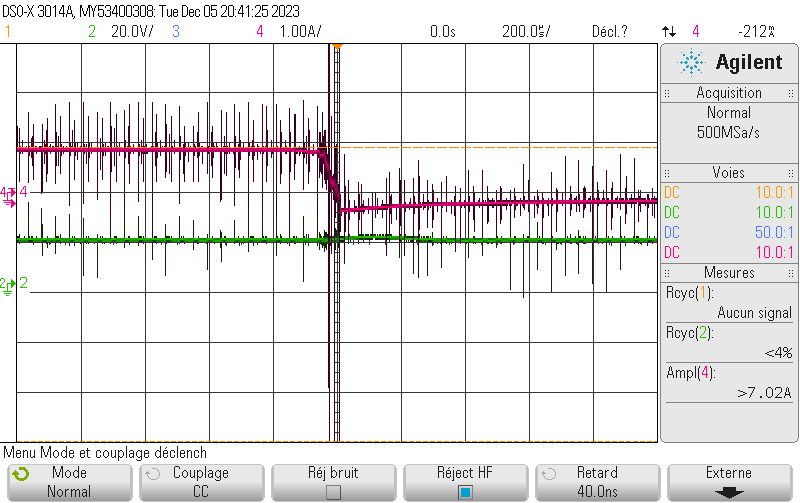

Branchement